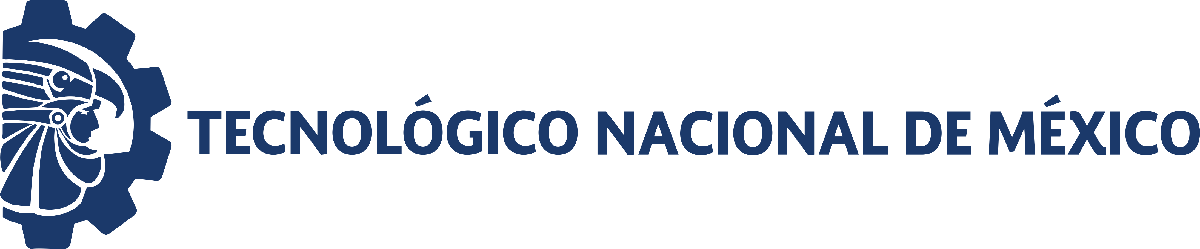                                 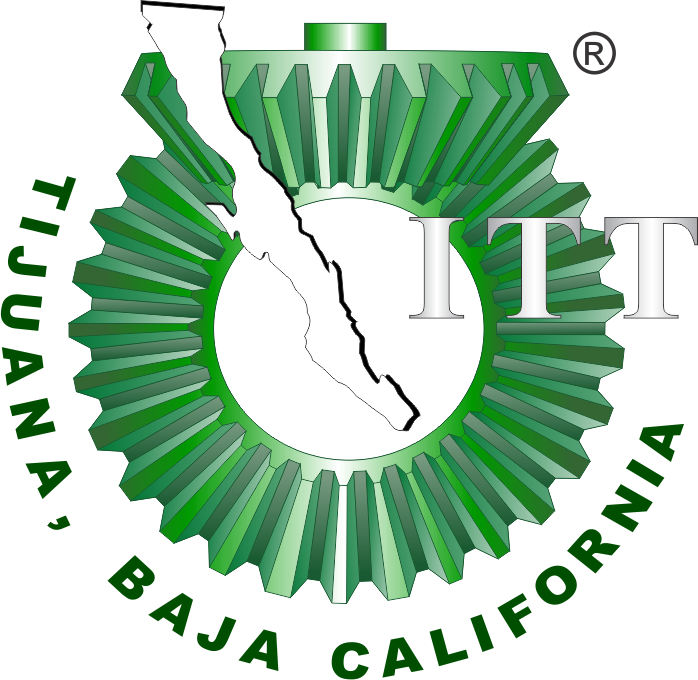

# Práctica 2: sistema respiratorio

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

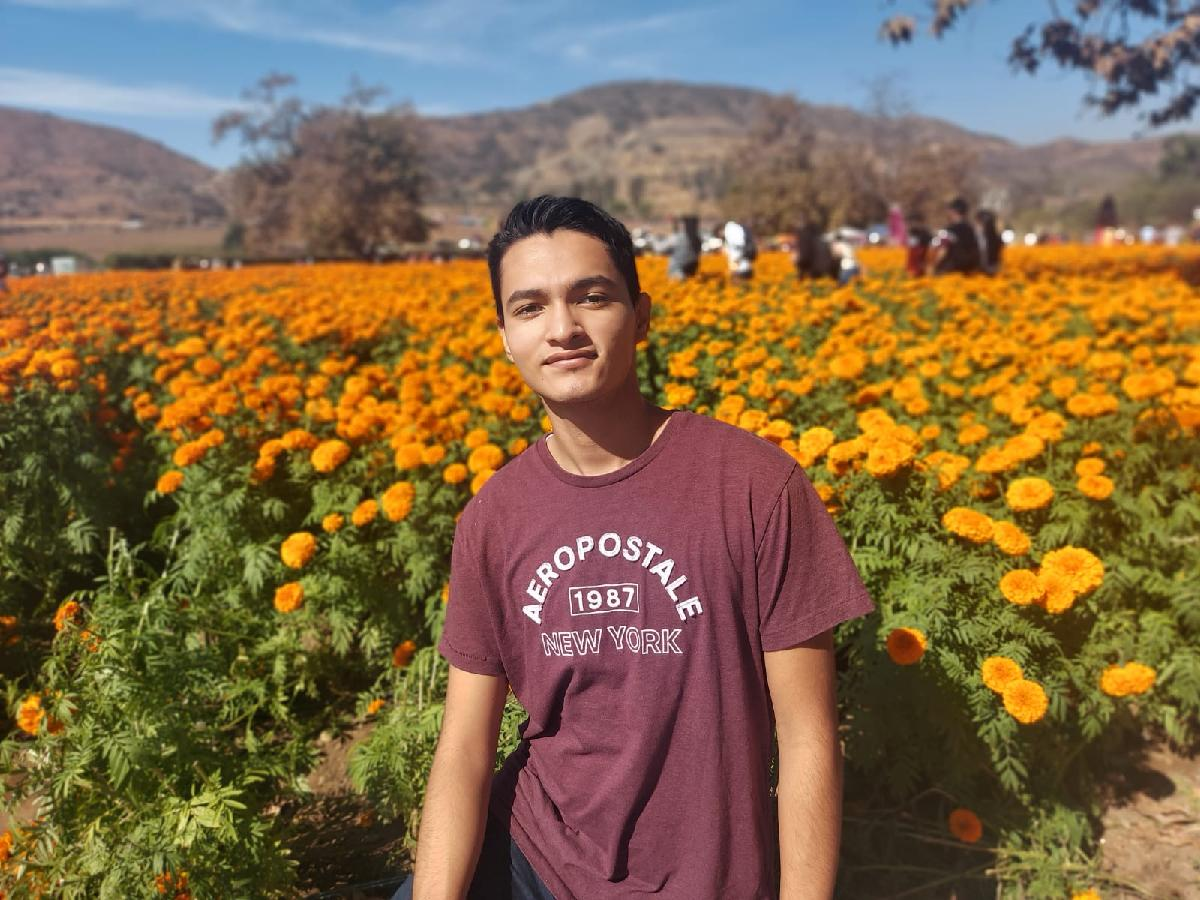

Nombre del alumno: **Armenta Contreras Odin Enrique**

**                                  Paniagua Fernandez Jaime Jhoelly**

**                                  Angel Ismael Venegas Ameca**

Número de control:  **21212140**

**                                21212171**

**                                21212184**

Correo institucional: **l21212140@tectijuana.edu.mx**

**                                 l21212171@tectijuana.edu.mx**

**                                 l21212184@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all');
tend = '10';
file = 'SistemaGastrico';
open_system(file);
parameters.StopTime = tend;
parameters.Solver = 'ode45';
parameters.MaxStep = '1E-3';

## Parametros del controlador y rendimiento


$$\begin{array}{l}
K_p =1154\ldotp 3384\\
P_I =54974\ldotp 1065\\
K_{D\;} =5\ldotp 3855\\
\textrm{Rise}\;\textrm{Time}=0\ldotp 000248\;\textrm{seconds}\\
\textrm{Setting}\;\textrm{Time}=0\ldotp 00188\;\textrm{seconds}\\
\textrm{Overshoot}=2\ldotp 32%\\
\textrm{Peak}\;1\ldotp 02
\end{array}$$


## Respuesta a Funcion Sinusoidal

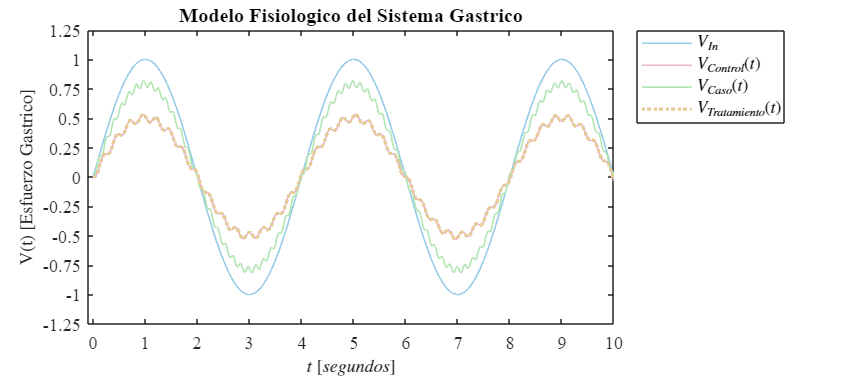

Signal = 'SistemaGastrico';
x1 = sim(file,parameters);
plotsignals(x1.t,x1.Pao,x1.PAx,x1.PAy,x1.PAz,Signal)

## Funciones

function plotsignals(t,Pao,PAx,PAy,PAz,Signal)
    set(figure(),'Color','w')
    set(gcf,'units','centimeters','position',[25,1.5,18,8])
    set(gca,'Fontname','Times New Roman','Fontsize',11)
    hold on; grid off, box on

    plot(t,Pao,'Linewidth',1,'Color',[0.6 0.8 0.9])
    plot(t,PAx,'Linewidth',1,'Color',[0.9 0.7 0.8])
    plot(t,PAy,'Linewidth',1,'Color',[0.7 0.9 0.7])  
    plot(t,PAz,':','Linewidth',2,'Color',[0.9 0.8 0.6])

    % Añadir leyenda
    % Añadir leyenda
    lgd = legend('show');

    % Cambiar la posición de la leyenda
    lgd.Location = 'northeastoutside'; % Cambiar 'northeastoutside' según necesites
    L = legend('$V_{In}$','$V_{Control}(t)$','$V_{Caso}(t)$','$V_{Tratamiento}(t)$');
    set(L, 'Interpreter','Latex','Fontsize',10,'box','on')

    xlabel('$t$ $[segundos]$','Interpreter','Latex','FontSize',11)
    ylabel('V(t) [Esfuerzo Gastrico]','Interpreter','Latex','FontSize',11)

    if Signal == "SistemaGastrico"
        title("Modelo Fisiologico del Sistema Gastrico")
        xlim([-0.1,10]); xticks(0:1:10)
        ylim([-1.25,1.25]); yticks(-1.25:0.25:1.25)
    end

    exportgraphics(gcf,[Signal,'.pdf'],'ContentType','vector')
    exportgraphics(gcf,[Signal,'.png'],'Resolution',700);
    print(Signal,'-dsvg','-r600');
    print(Signal,'-depsc','-r600');
end